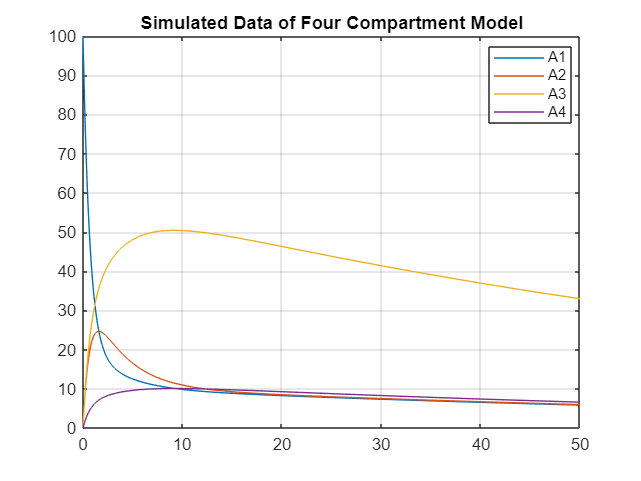

clc, clearvars, close all
syms A1(t) A2(t) A3(t) A4(t)

k10 = 0.1; %elimination
k12 = 0.5;% central to liver
k21 = 0.5; % liver to central
k13 = 0.5; % central to tumour
k31 = 0.1; % tumour to central
k14 = 0.1; % central to healthy cells
k41 = 0.1; % healthy cells to central
C0 = 100;

tf=50;

ode1 = diff(A1,t) == -k10 * A1 - k12 * A1 + k21 * A2 - k13 * A1 + k31 * A3 - k14 * A1 + k41 * A4;
ode2 = diff(A2,t) == k12 * A1 - k21 * A2;
ode3 = diff(A3,t) == k13 * A1 - k31 * A3;
ode4 = diff(A4, t) == k14* A1 - k41 * A4;
odes = [ode1; ode2; ode3; ode4]; 

% initial conditions
cond1 = A1(0) == C0;
cond2 = A2(0) == 0;
cond3 = A3(0) == 0;
cond4 = A4(0) == 0;
conds = [cond1; cond2; cond3; cond4];

% Compute Solutions
[A1Sol(t), A2Sol(t), A3Sol(t), A4Sol(t)] = dsolve(odes, conds);

% plot theoretical data
fplot(A1Sol,[0 tf]) 
hold on
fplot(A2Sol, [0 tf])
grid on
fplot(A3Sol, [0 tf])
fplot(A4Sol, [0 tf])
legend("A1","A2", "A3", "A4", Location = "best");
title('Simulated Data of Four Compartment Model')
hold off

tiledlayout(2,2)

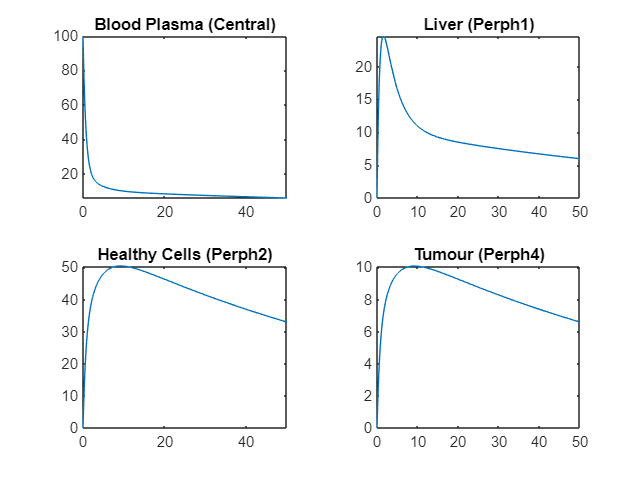

nexttile
fplot(A1Sol,[0 tf]) 
title('Blood Plasma (Central)')
nexttile
fplot(A2Sol, [0 tf])
title('Liver (Perph1)')
nexttile
fplot(A3Sol, [0 tf])
title('Healthy Cells (Perph2)')
nexttile
fplot(A4Sol, [0 tf])
title('Tumour (Perph4)')